# nature cubic spline(equal distance)

## parameters

h=0.25;
x=0:h:1;
n=length(x);
a=cos(pi*x)';%系数a的向量，根据f(xi)=a(i)即得

## calculate Ac=B

## 计算系数向量b,c,d，每个系数向量有n-1个分量，对应n-1个函数

B=zeros(n,1);
A=zeros(n,n);
A(1,1)=1;A(n,n)=1;
for i=2:n-1
    B(i)=3*(a(i+1)-2*a(i)+a(i-1))/h;
    A(i,i-1)=h;A(i,i)=4*h;A(i,i+1)=h;
end
c=A^-1*B;
d=ones(n-1,1);
b=ones(n-1,1);
for i=1:n-1
   d(i)=(c(i+1)-c(i))/(3*h);
   b(i)=(a(i+1)-a(i))/h-(2*c(i)+c(i+1))*h/3;
end

## Produce Function

# 根据上一模块计算的系数向量，批量生成函数句柄

（函数句柄是可以带入数值计算的公式，这使得后续计算积分更容易）

F=cell(n-1,1);%使用cell()生成元胞数组，装函数句柄
for i=1:n-1
    a_i=['@(x)',num2str(a(i)),'+'];%生成系数a对应的字符串
    b_i=[num2str(b(i)),'*','(x-',num2str(x(i)),')','+'];%生成系数b对应的字符串
    c_i=[num2str(c(i)),'*','(x-',num2str(x(i)),').^2','+'];%生成系数c对应的字符串
    d_i=[num2str(d(i)),'*','(x-',num2str(x(i)),').^3'];%生成系数d对应的字符串
    str=[a_i,b_i,c_i,d_i];%拼接各部分字符串
    F{i}=str2func(str);%将拼接好的字符串转化为函数句柄
end
F%输出函数句柄，共n-1个，本题是4个

F =     @(x)1+-0.75736*(x-0)+0*(x-0).^2+-6.6274*(x-0).^3                      
    @(x)0.70711+-2*(x-0.25)+-4.9706*(x-0.25).^2+6.6274*(x-0.25).^3        
    @(x)6.1232e-17+-3.2426*(x-0.5)+4.4409e-16*(x-0.5).^2+6.6274*(x-0.5).^3
    @(x)-0.70711+-2*(x-0.75)+4.9706*(x-0.75).^2+-6.6274*(x-0.75).^3       


## plot

# 绘图模块

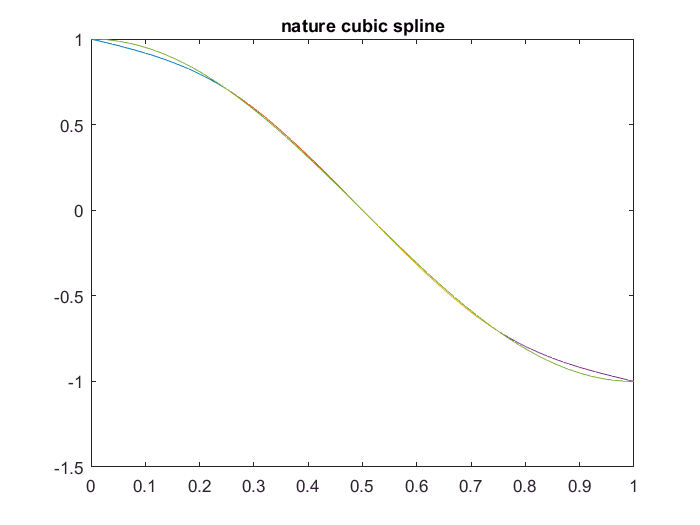

h2=0.01;
for i=1:n-1
    plot(x(i):h2:x(i+1),F{i}(x(i):h2:x(i+1))),
    hold on
end
h3=0.01;
plot(x(1):h3:x(n),cos(pi*(x(1):h3:x(n))))
title('nature cubic spline')

## integral

# 积分计算模块

inte_gral=[n-1,1];
for i=1:n-1
    inte_gral(i)=integral(F{i},x(i),x(i+1));
end
sum(inte_gral)

ans =        1.2500000000637e-06
